m=@(x,y) y-3.*x;
yexact=@(x) 7*exp(x)+3*x+3;

y0=10
x0=0
xf=3
h=1
x=x0:h:xf

y_Euler=RK2(m, x0, xf, y0, h, 0);
y_Heun=RK2(m, x0, xf, y0, h, 0.5);

q = 1

y_Midpoint=RK2(m, x0, xf, y0, h, 1);

q = 0.5000

y_Ralston=RK2(m, x0, xf, y0, h, 2/3);

q = 0.7500

y_Alvaro=RK2(m, x0, xf, y0, h, 777);

q = 6.4350e-04

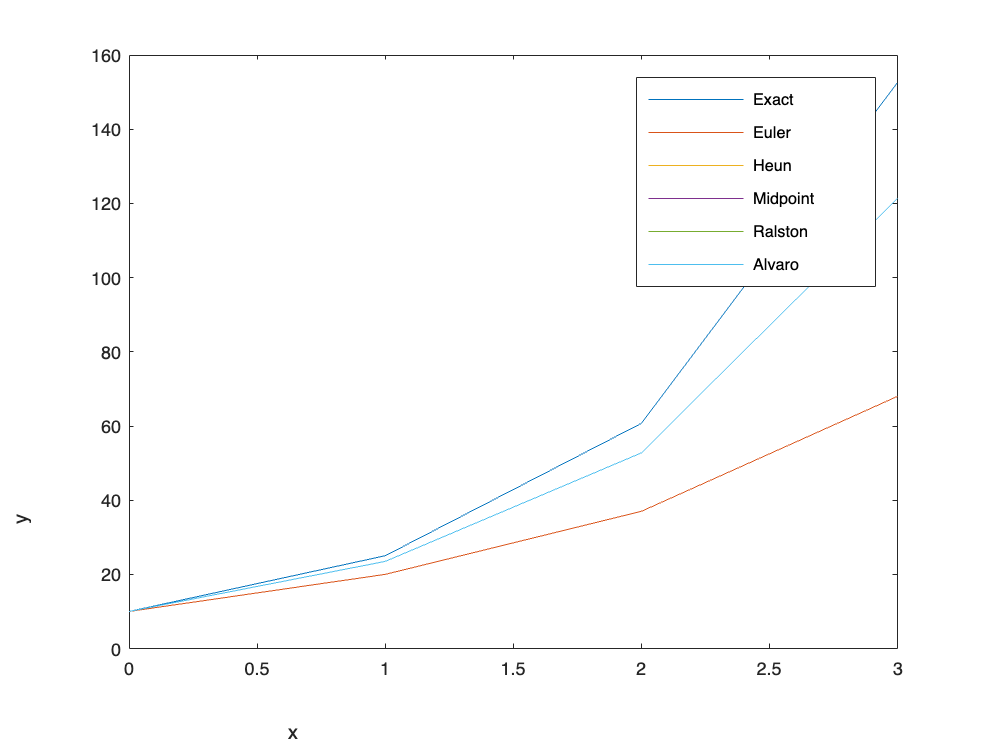


plot(x,yexact(x))
hold on
plot(x,y_Euler)
plot(x,y_Heun)
plot(x,y_Midpoint)
plot(x,y_Ralston)
plot(x,y_Alvaro)
hold off



xlabel("x")
ylabel("y")
legend("Exact", "Euler","Heun", "Midpoint", "Ralston","Alvaro")